data=obtain_data('rf',3)

data =     0.0001   -0.0001    0.0001   -0.0001    0.0000   -0.0001   -0.0000    0.0000    0.0001    0.0001   -0.0001    0.0000    0.0001    0.0000    0.0001    0.0000   -0.0000   -0.0000    0.0002   -0.0000   -0.0000    0.0000    0.0002    0.0000    0.0002    0.0002   -0.0000   -0.0001    0.0000   -0.0000    0.0002    0.0001   -0.0002   -0.0000    0.0002   -0.0001   -0.0002    0.0003    0.0002   -0.0005    0.0003    0.0007   -0.0004   -0.0003    0.0000    0.0008    0.0006   -0.0058    0.0062    0.0076


baseline=obtain_baseline('rf',3)

baseline =    -0.0000    0.0000   -0.0000   -0.0002   -0.0001   -0.0001   -0.0000    0.0000    0.0000    0.0001   -0.0000   -0.0001   -0.0001    0.0001    0.0000    0.0001    0.0000   -0.0001   -0.0001   -0.0001    0.0001    0.0000   -0.0001   -0.0001    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0000   -0.0002   -0.0000    0.0001   -0.0002   -0.0002    0.0002    0.0001   -0.0006    0.0002    0.0007   -0.0005   -0.0003    0.0001    0.0009    0.0006   -0.0056    0.0063    0.0077


x=[1:1520]

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t=x/(23.328e9)

t =    1.0e-08 *

    0.0043    0.0086    0.0129    0.0171    0.0214    0.0257    0.0300    0.0343    0.0386    0.0429    0.0472    0.0514    0.0557    0.0600    0.0643    0.0686    0.0729    0.0772    0.0814    0.0857    0.0900    0.0943    0.0986    0.1029    0.1072    0.1115    0.1157    0.1200    0.1243    0.1286    0.1329    0.1372    0.1415    0.1457    0.1500    0.1543    0.1586    0.1629    0.1672    0.1715    0.1758    0.1800    0.1843    0.1886    0.1929    0.1972    0.2015    0.2058    0.2100    0.2143


a=abs(hilbert_downconvert(data-baseline,3));
plot(t,a)
hold on;
plot(t,zeros(1,1520));

ylim([-1,1])

[max_val index_max] = max(a)

max_val = 0.0222

index_max = 141

index_max

index_max = 141


y1=get(gca,'ylim')

y1 =     -1     1


hold on
plot([t(index_max) t(index_max)],y1)

t_increment=t(2)-t(1)

t_increment = 4.2867e-11

b=round((0.9e-9)/t_increment)

b = 21

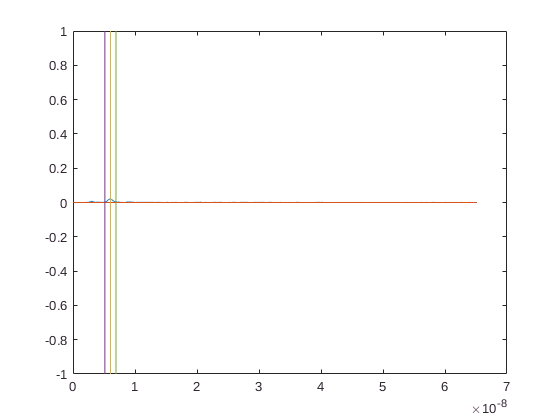

hold on;
plot([t(index_max-b) t(index_max-b)],y1)
hold on;
plot([t(index_max+b) t(index_max+b)],y1)